# Procesat morfològic 3

## Dilatació multinivell

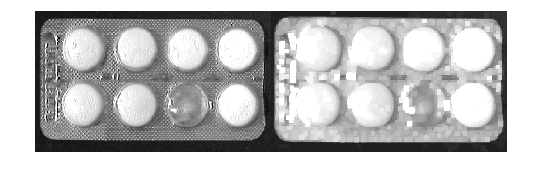

I = imread('astablet.tif');
SE = ones(5, 5);
ID = imdilate(I,SE);
montage({I,ID});

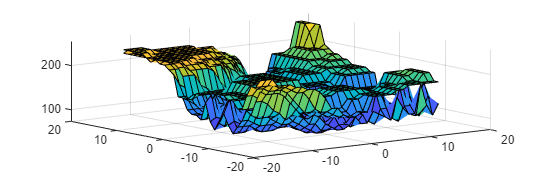

[f c] = size(I);
Icrop = I(floor(f/2)-15:floor(f/2)+15,floor(c/2)-15:floor(c/2)+15);
IDcrop = ID(floor(f/2)-15:floor(f/2)+15,floor(c/2)-15:floor(c/2)+15);
[X,Y] = meshgrid(-15:15);
surf(X,Y,IDcrop);
hold on
surf(X,Y,Icrop);
hold off

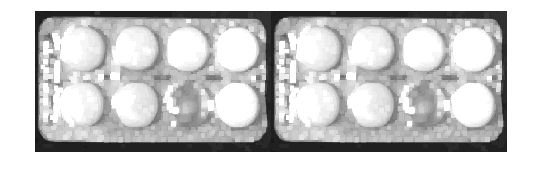

% dilatacio = max veïns
ID2 = colfilt(I,[5,5], 'sliding', @max);
montage({ID,ID2});

## Erosió multinivell

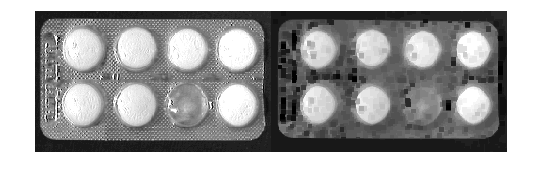

IE = imerode(I,SE);
montage({I,IE});

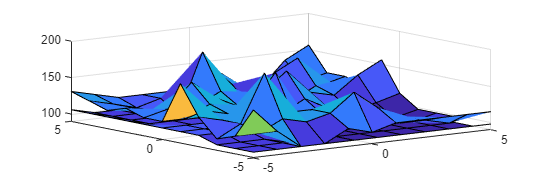

Icrop = I(floor(f/2)-5:floor(f/2)+5,floor(c/2)-5:floor(c/2)+5);
IEcrop = IE(floor(f/2)-5:floor(f/2)+5,floor(c/2)-5:floor(c/2)+5);
[X,Y] = meshgrid(-5:5);
surf(X,Y,IEcrop);
hold on
surf(X,Y,Icrop);
hold off

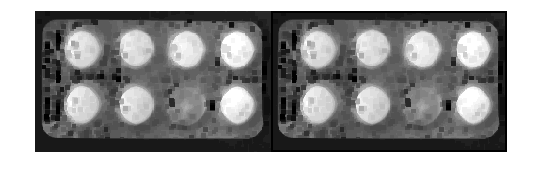

% erosió = min veïns
IE2 = colfilt(I,[5,5], 'sliding', @min);
montage({IE,IE2});

## Open multinivell

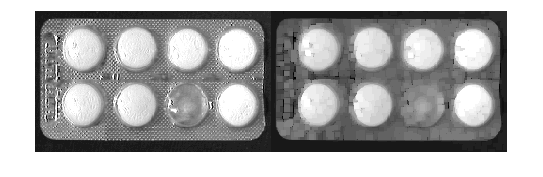

IO = imopen(I,SE);
montage({I,IO});

## Close multinivell

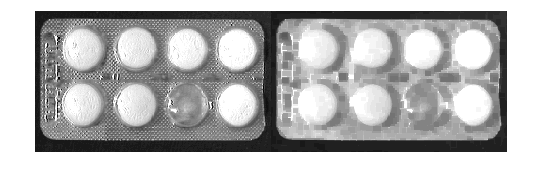

IC = imclose(I,SE);
montage({I,IC});

## Open-close multinivell

Filtre = eliminar soroll

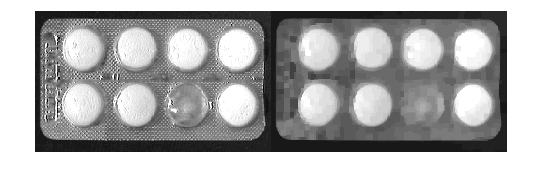

IOC = imclose(IO,SE);
montage({I,IOC});

## Filtre multinivell

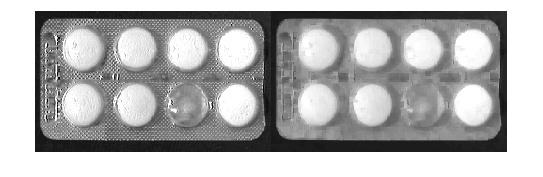

IOCF = uint8((double(IO)+double(IC))/2);
montage({I,IOCF});

## Residus

### Residu intern

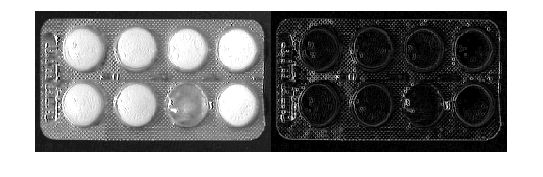

I = imread('astablet.tif');
SE = ones(3, 3);
IE = imerode(I,SE);
RI = I - IE; % enaltir contorn morfològic
montage({I,RI});

### Residu extern

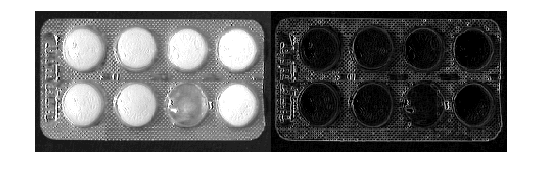

ID = imdilate(I,SE);
RE = ID - I; % enaltir contorn morfològic
montage({I,RE});

### Residu Laplacià

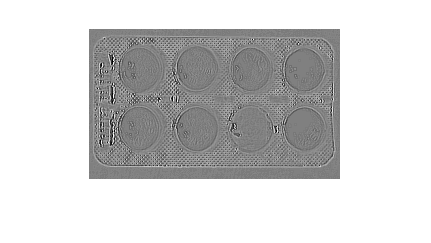

RL = double(RE) - double(RI);
imshow(RL,[]);

### Residu Top-Hat

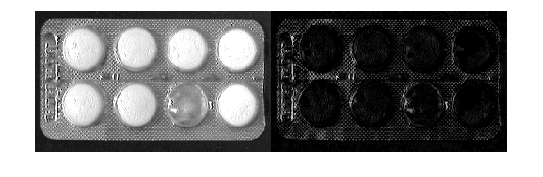

SE = ones(5, 5);
IO = imopen(I,SE);
TH = I - IO;
montage({I,TH});

### Residu Bottom-Hat

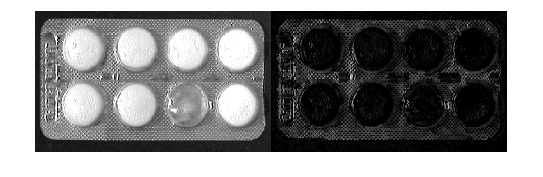

IC = imclose(I,SE);
BH = IC-I;
montage({I,BH});

## Aplicació de Top-Hat

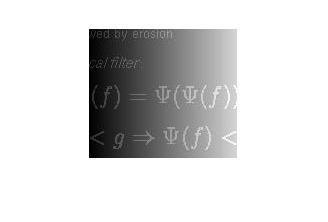

I = imread('nshadow.tif');
imshow(I);

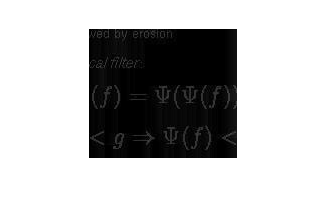

SE = ones(25, 25);
IO = imopen(I,SE);
TH = I - IO;
imshow(TH);

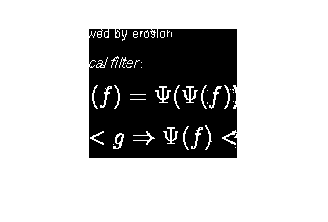

t = otsuthresh(imhist(TH));
imshow(TH > 255*t);

## Reconstrucció multinivell

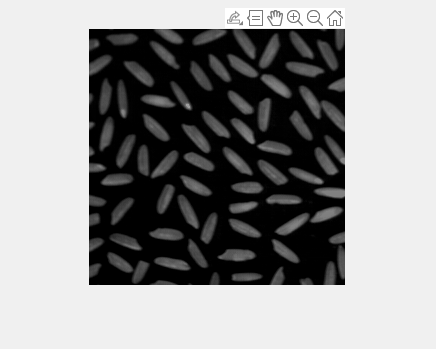

I = imread('arros.tif');
SE = ones(25, 25);
IO = imopen(I,SE);
TH = I - IO;
imshow(TH);
[x,y] = getpts;

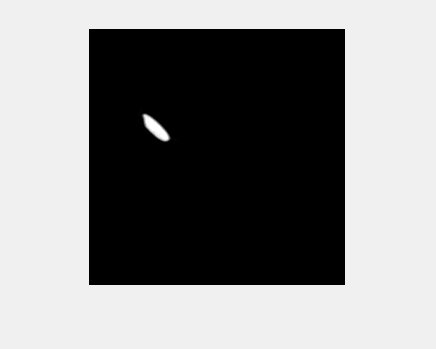

MARK = uint8(zeros(size(TH)));
MARK(uint16(y),uint16(x)) = 255;
REC = imreconstruct(MARK,TH);
imshow(REC,[]);

## Màxims regionals

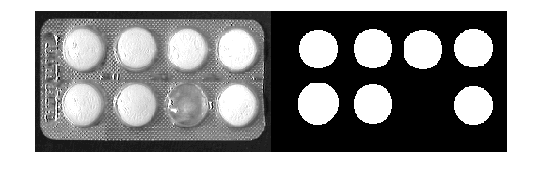

I = imread('astablet.tif');
IM = imregionalmax(I); % masses màxims regionals per detectar pastilles
SE = fspecial('disk',20) > 0; % SE = strel()
IO = imopen(I, SE);
IOM = imregionalmax(IO);
montage({I,IOM});

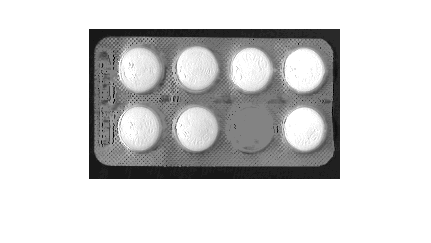

IM2 = I;
IM2(not(IOM)) = 0;
REC = imreconstruct(IM2,I);
imshow(REC,[]);

## Exercici realitzar plot de granulometria

Plot que mostra mida vs nombre

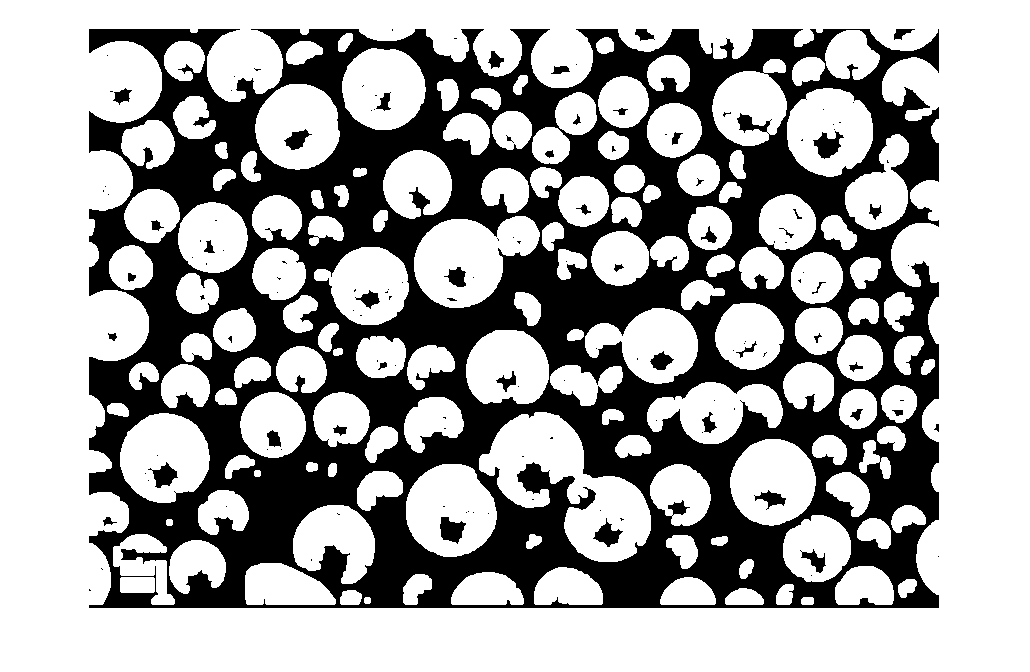

I = imread('granulometria2.png');
for i=1:50
    SE = fspecial('disk',i) > 0;
    IO = imopen(I,SE); 
    t = max(32,255*otsuthresh(imhist(IO)));
    BW = IO > t;
    C = bwconncomp(BW);
    V(i) = C.NumObjects;
    imshow(BW);
end